# CNN Spectrogram Algorithm

Here is an example of using transfer learning to fine tune existing deep networks. The models can pretty quickly overtrain and produce 100% validation accuracy on the simulated spectrogram images that are in the CNN_Spectrogram_Algorithm folder, but this is a good starting place.s

## Adapted from MATLAB example: Transfer Learning Using Pretrained Network

see also: Train Deep Learning Network to Classify New Images

This example shows how to fine-tune a pretrained GoogLeNet convolutional neural network to perform classification on a new collection of images.

GoogLeNet has been trained on over a million images and can classify images into 1000 object categories (such as keyboard, coffee mug, pencil, and many animals). The network has learned rich feature representations for a wide range of images. The network takes an image as input and outputs a label for the object in the image together with the probabilities for each of the object categories.

Transfer learning is commonly used in deep learning applications. You can take a pretrained network and use it as a starting point to learn a new task. Fine-tuning a network with transfer learning is usually much faster and easier than training a network with randomly initialized weights from scratch. You can quickly transfer learned features to a new task using a smaller number of training images.

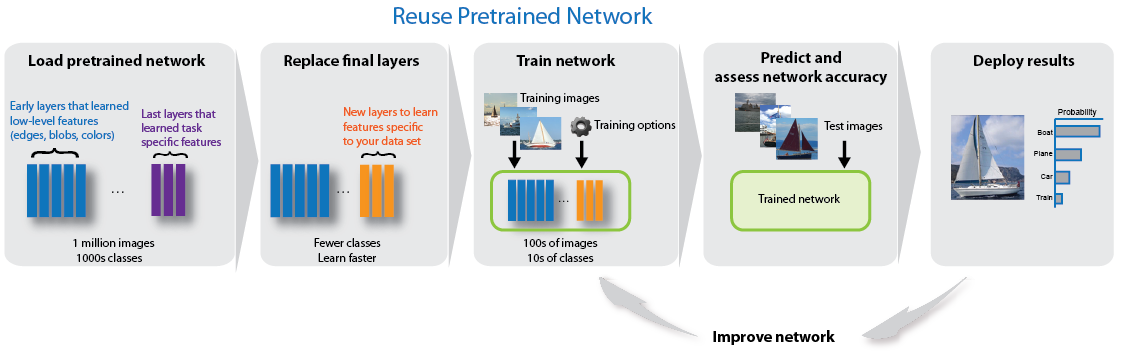

wd = '~/Documents/GitHub/srdl-hack/CNN_Spectrogram_Algorithm/Demo-Training/';
imdsTrain = imageDatastore([wd 'train'] ...
    , 'IncludeSubfolders', true ...
    , 'LabelSource','foldernames' ...
    );
imdsValidate = imageDatastore([wd 'valid'] ...
    , 'IncludeSubfolders', true ...
    , 'LabelSource','foldernames' ...
    );

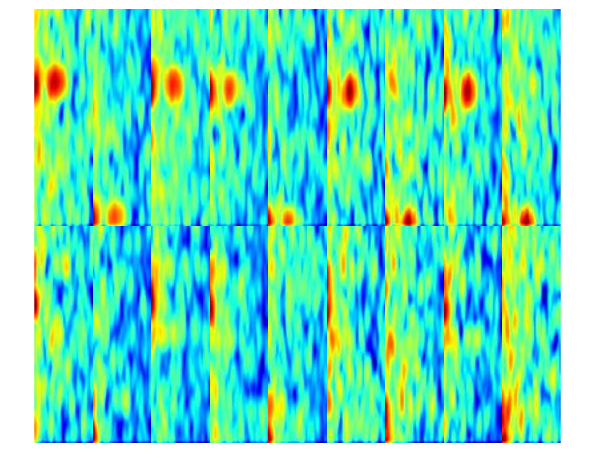

% Look at a few examples of the training spectrograms
figure
montage(imdsTrain.Files( ...
    [find(imdsTrain.Labels == "Yes", 9); ...
    find(imdsTrain.Labels == "No", 9)]) ...
    , "size", [2, inf]);

## Load Pretrained Network

Load the pretrained GoogLeNet neural network. If Deep Learning Toolbox™ Model *for GoogLeNet Network* is not installed, then the software provides a download link.

net = googlenet;

Use `deepNetworkDesigner` to display an interactive visualization of the network architecture and detailed information about the network layers.

deepNetworkDesigner(net)

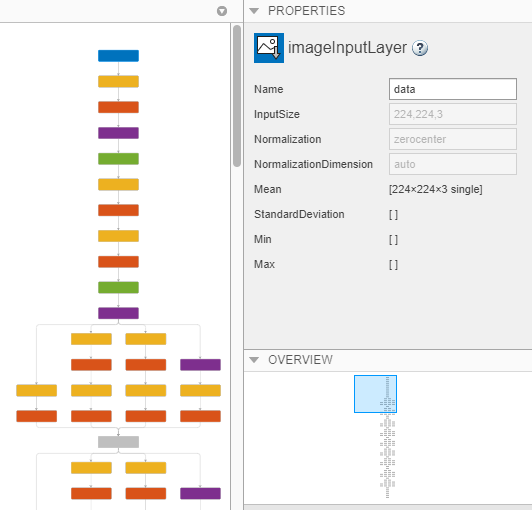

The first layer, which is the image input layer, requires input images of size 224-by-224-by-3, where 3 is the number of color channels. 

inputSize = net.Layers(1).InputSize

inputSize =    224   224     3


## Replace Final Layers

The fully connected layer and classification layer of the pretrained network `net` are configured for 1000 classes. These two layers, `loss3-classifier` and `output` in GoogLeNet, contain information on how to combine the features that the network extracts into class probabilities, a loss value, and predicted labels. To retrain a pretrained network to classify new images, replace these two layers with new layers adapted to the new data set.

Extract the layer graph from the trained network.

lgraph = layerGraph(net); 

Replace the fully connected layer with a new fully connected layer that has number of outputs equal to the number of classes. To make learning faster in the new layers than in the transferred layers, increase the `WeightLearnRateFactor` and `BiasLearnRateFactor` values of the fully connected layer.

numClasses = numel(categories(imdsTrain.Labels))

numClasses = 2

newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...  % these are from the matlab example
    'BiasLearnRateFactor',10);
    
lgraph = replaceLayer(lgraph,'loss3-classifier',newLearnableLayer);

The classification layer specifies the output classes of the network. Replace the classification layer with a new one without class labels. `trainNetwork` automatically sets the output classes of the layer at training time.

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);

## Train Network (GoogLeNet)

The network requires input images of size 224-by-224-by-3, but the images in the image datastores have different sizes. Use an augmented image datastore to automatically resize the training images. Specify additional augmentation operations to perform on the training images: randomly flip the training images along the vertical axis, and randomly translate them up to 30 pixels horizontally and vertically. Data augmentation helps prevent the network from overfitting and memorizing the exact details of the training images.  

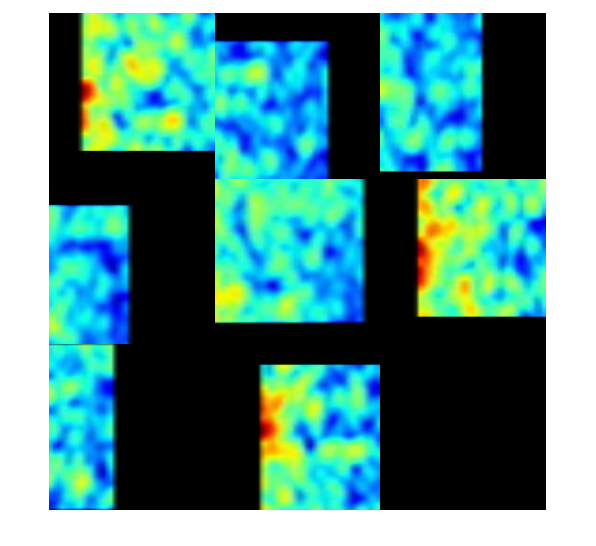

% This seems suspect, but even with it, the model still overtrains and
% gives 100% accuracy on the validation data.
pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandYReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore( ...
    inputSize(1:2),imdsTrain ...
    , "OutputSizeMode", "resize" ...
    , 'DataAugmentation',imageAugmenter ...
    );

figure
montage(augimdsTrain.preview.input)

To automatically resize the validation images without performing further data augmentation, use an augmented image datastore without specifying any additional preprocessing operations.

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidate);

Specify the training options. For transfer learning, keep the features from the early layers of the pretrained network (the transferred layer weights). To slow down learning in the transferred layers, set the initial learning rate to a small value. In the previous step, you increased the learning rate factors for the fully connected layer to speed up learning in the new final layers. This combination of learning rate settings results in fast learning only in the new layers and slower learning in the other layers. When performing transfer learning, you do not need to train for as many epochs. An epoch is a full training cycle on the entire training data set. Specify the mini-batch size and validation data. The software validates the network every `ValidationFrequency` iterations during training.

minibatchSize = 10;
validationFreq = floor(numel(imdsTrain.Files)/minibatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',minibatchSize, ...
    'MaxEpochs',3, ...
    'InitialLearnRate',1e-3, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',validationFreq, ...
    'Verbose',false, ...
    'Plots','training-progress' ...
    );

Train the network consisting of the transferred and new layers. By default, `trainNetwork` uses a GPU if one is available. This requires Parallel Computing Toolbox™ and a supported GPU device. For information on supported devices, see [GPU Support by Release](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Otherwise, it uses a CPU. You can also specify the execution environment by using the `'ExecutionEnvironment'` name-value pair argument of `trainingOptions`.

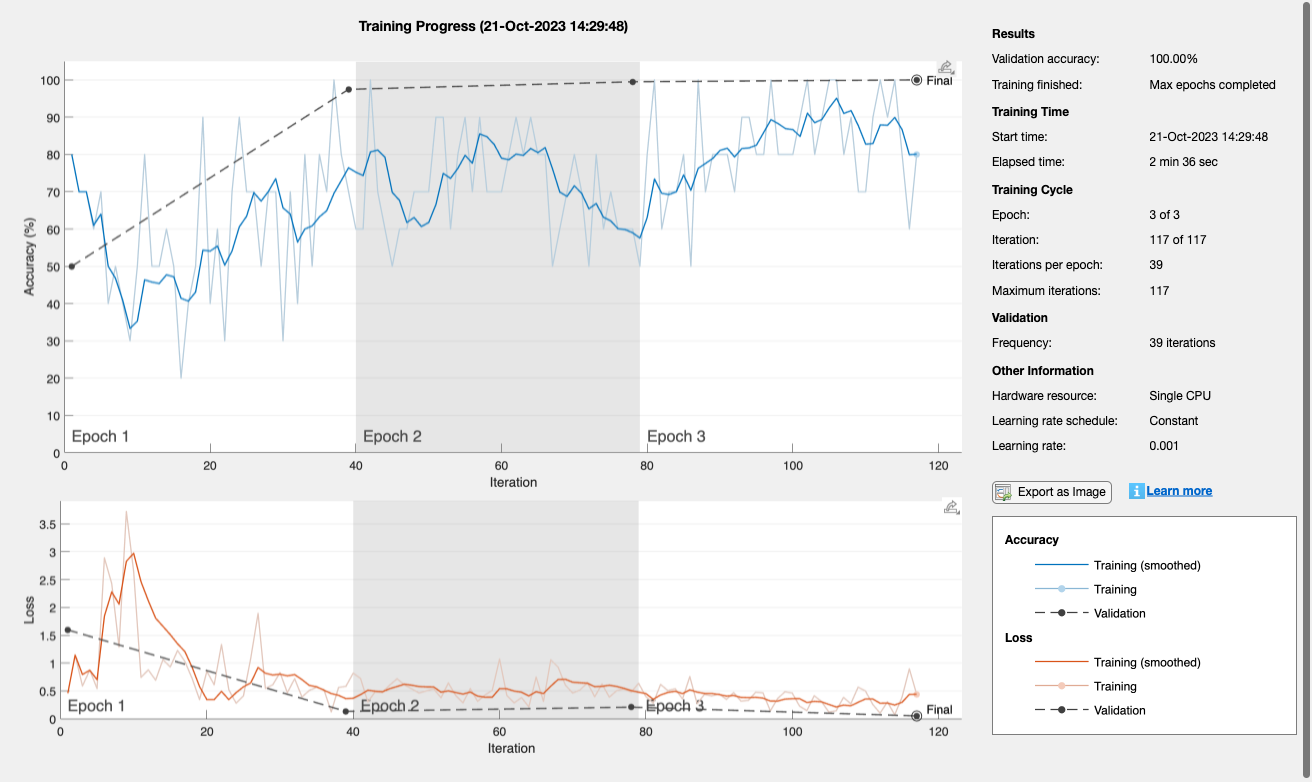

netTransfer = trainNetwork(augimdsTrain,lgraph,options);

On my laptop, it took 3 minutes to fine tune GoogleNet... and training accuracy is 100%.

## 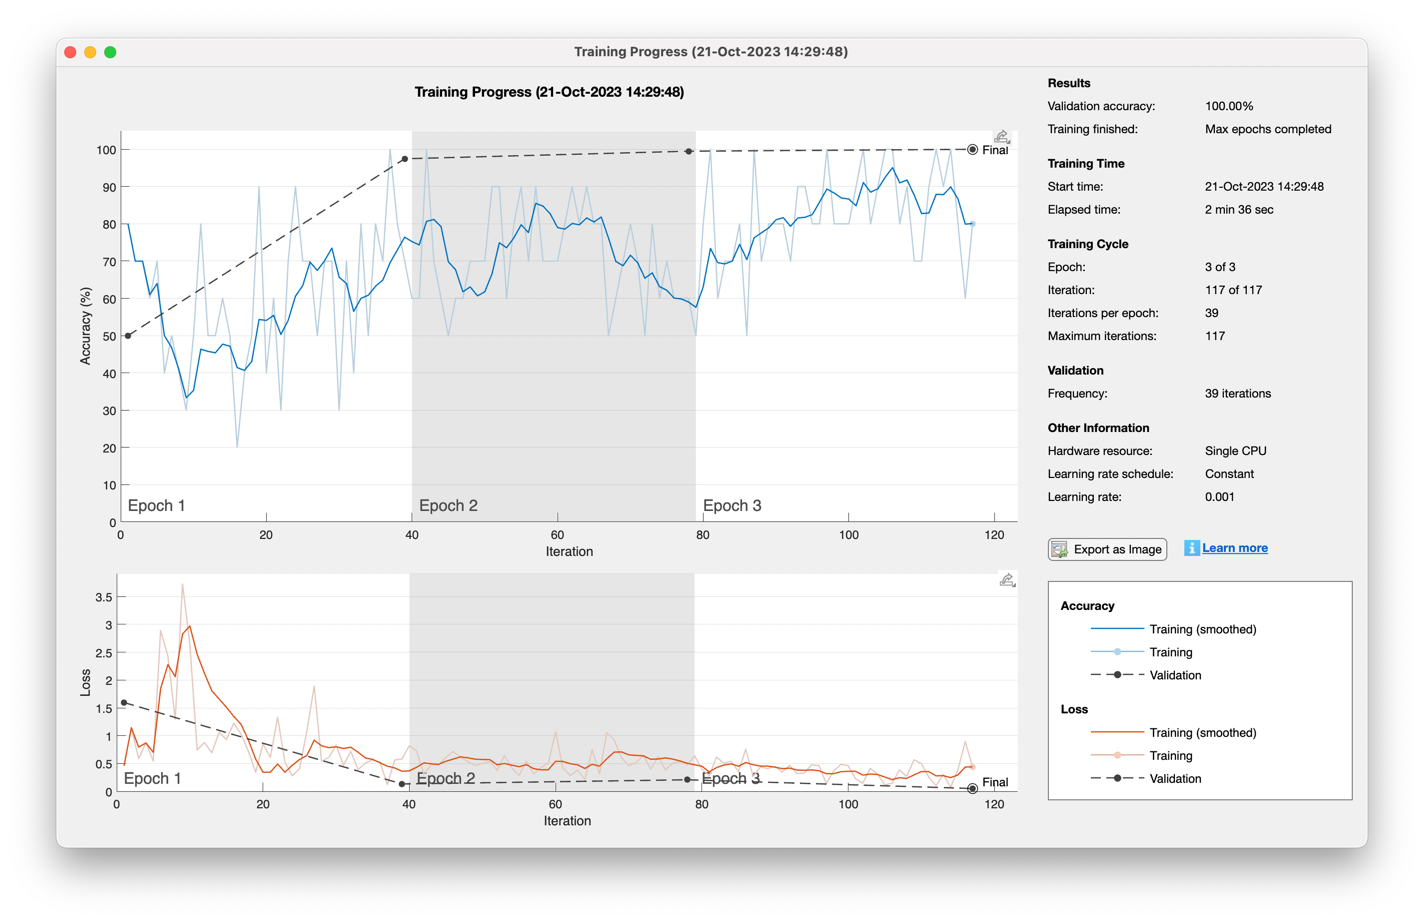

## Train Network (ResNet-18)

Now, we can repeat the process with a different pre-trained model (ResNet-18).

net = resnet18;
analyzeNetwork(net)

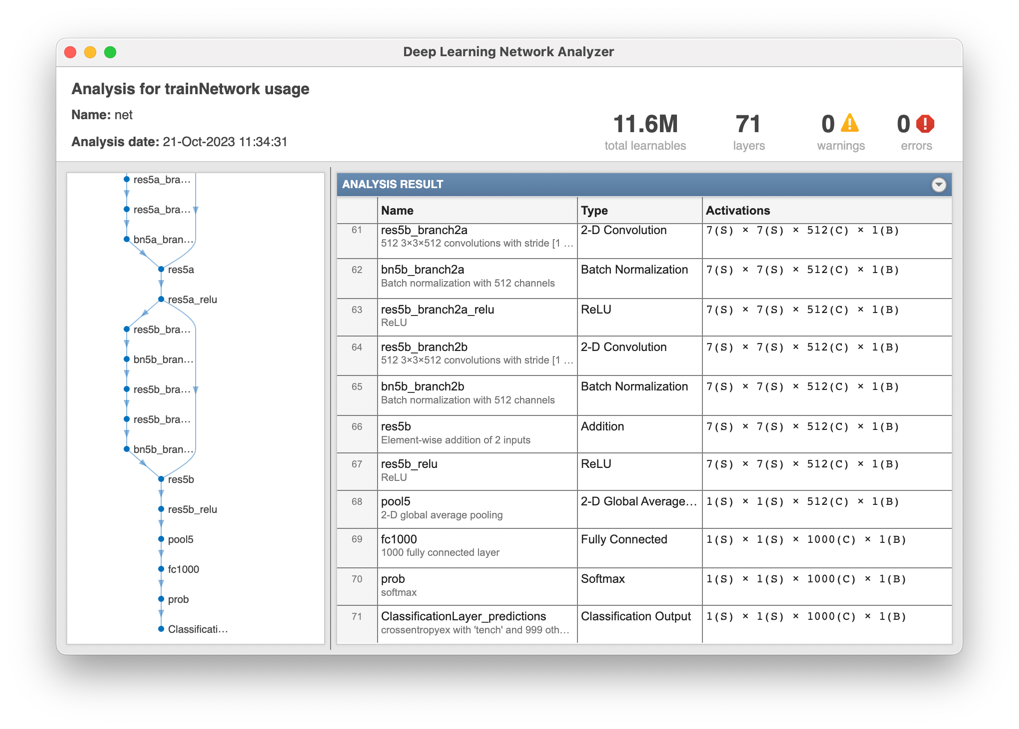

Convert the trained network to a layer graph and replace the last learnable layer (fc1000) and the classification output layer (ClassificationLayer_predictions). The function `findLayersToReplace` finds these layers automatically.

lgraph = layerGraph(net);  
[learnableLayer, classLayer] = findLayersToReplace(lgraph);
disp(learnableLayer)

  FullyConnectedLayer with properties:

          Name: 'fc1000'

   Hyperparameters
     InputSize: 512
    OutputSize: 1000

   Learnable Parameters
       Weights: [1000×512 single]
          Bias: [1000×1 single]

  Show all properties



disp(classLayer)

  ClassificationOutputLayer with properties:

            Name: 'ClassificationLayer_predictions'
         Classes: [1000×1 categorical]
    ClassWeights: 'none'
      OutputSize: 1000

   Hyperparameters
    LossFunction: 'crossentropyex'



In most networks, the last layer with learnable weights is a fully connected layer. Replace this fully connected layer with a new fully connected layer with the number of outputs equal to the number of classes in the new data set (5, in this example). In some networks, such as SqueezeNet, the last learnable layer is a 1-by-1 convolutional layer instead. In this case, replace the convolutional layer with a new convolutional layer with the number of filters equal to the number of classes. To learn faster in the new layer than in the transferred layers, increase the learning rate factors of the layer.

newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...  % these are from the matlab example
    'BiasLearnRateFactor',10);
    
lgraph = replaceLayer(lgraph, learnableLayer.Name, newLearnableLayer);


The classification layer specifies the output classes of the network. Replace the classification layer with a new one without class labels. `trainNetwork` automatically sets the output classes of the layer at training time. 

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph, classLayer.Name, newClassLayer);

To check that the new layers are connected correctly, plot the new layer graph and zoom in on the last layers of the network.

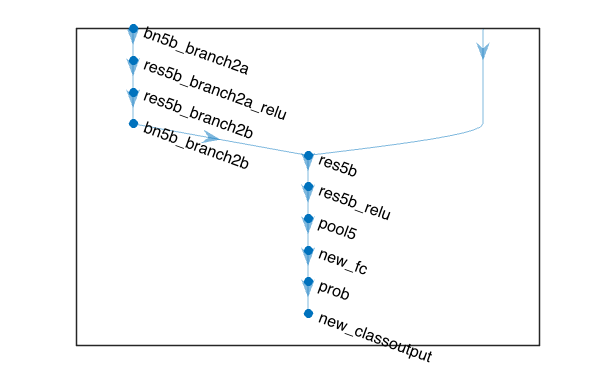

figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])

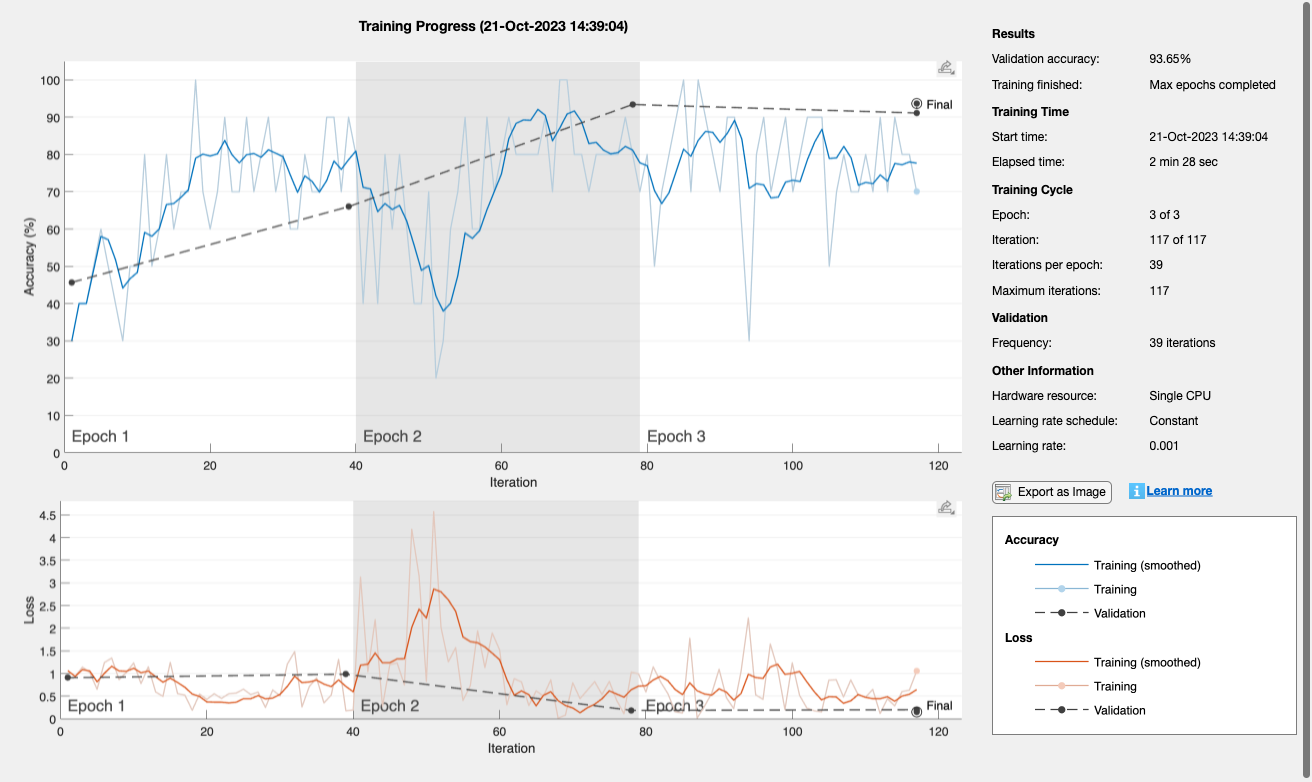

netTransferResNet = trainNetwork(augimdsTrain,lgraph,options);

This one didn't quite converge.

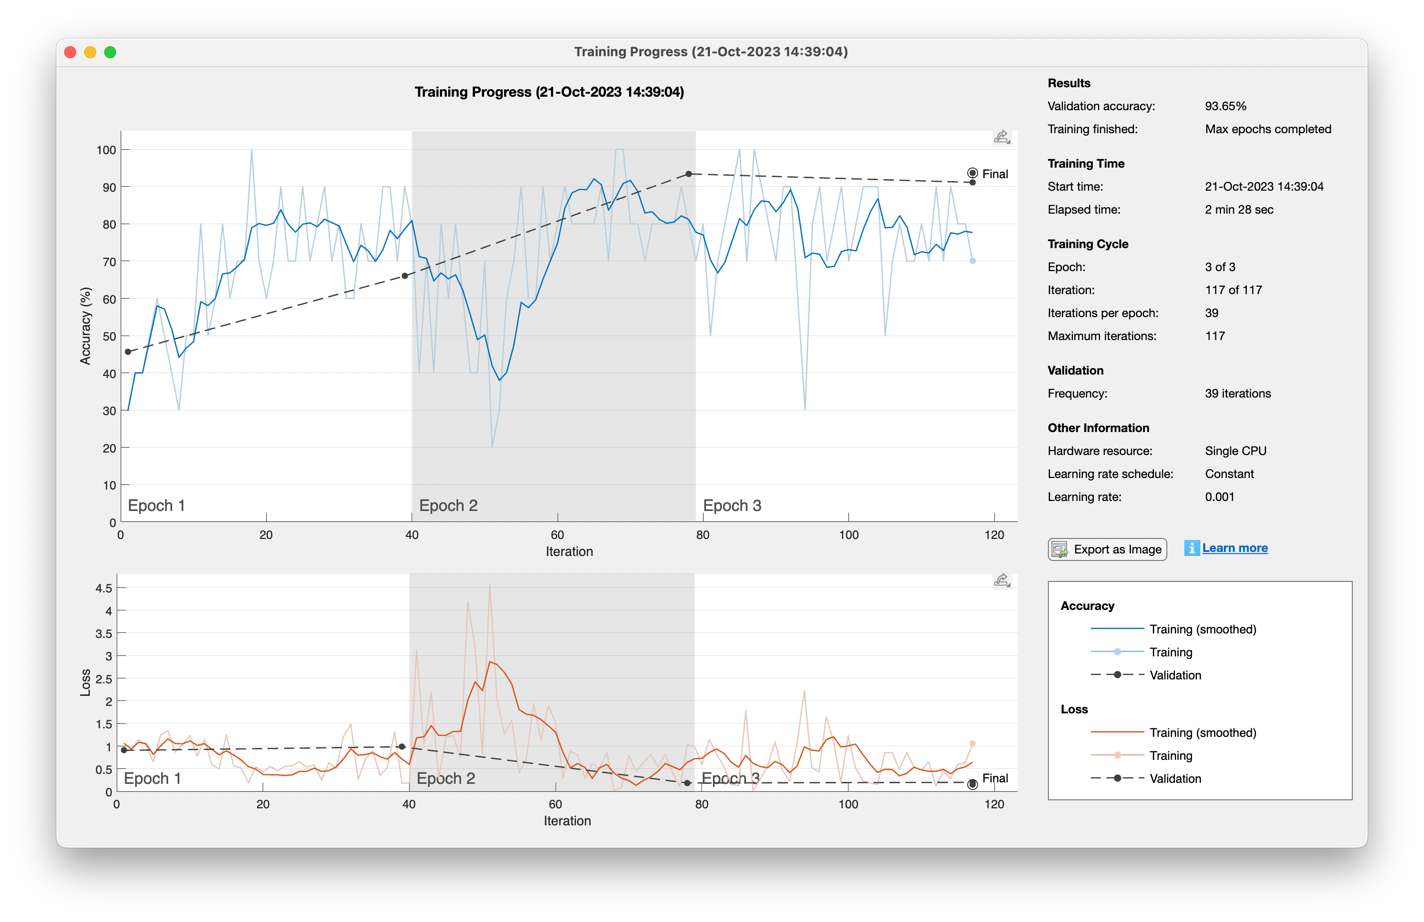

## Train Network (Freeze Initial Layers)

Optionally, you can "freeze" the weights of earlier layers in the network by setting the learning rates in those layers to zero. During training, `trainNetwork` does not update the parameters of the frozen layers. Because the gradients of the frozen layers do not need to be computed, freezing the weights of many initial layers can significantly speed up network training. If the new data set is small, then freezing earlier network layers can also prevent those layers from overfitting to the new data set.

Extract the layers and connections of the layer graph and select which layers to freeze. In GoogLeNet, the first 10 layers make out the initial 'stem' of the network. Use the supporting function [freezeWeights](matlab:edit(fullfile(matlabroot,'examples','nnet','main','freezeWeights.m'))) to set the learning rates to zero in the first 10 layers. Use the supporting function [createLgraphUsingConnections](matlab:edit(fullfile(matlabroot,'examples','nnet','main','createLgraphUsingConnections.m'))) to reconnect all the layers in the original order. The new layer graph contains the same layers, but with the learning rates of the earlier layers set to zero.

layers = lgraph.Layers;
connections = lgraph.Connections;


% I'm going to freeze 12 layers here instead of 10 since that looks like
% the first block of the ResNet network. I didn't give this much thought.
layers(1:12) = freezeWeights(layers(1:12));
lgraph = createLgraphUsingConnections(layers,connections);

Train the network using the training data. By default, `trainNetwork` uses a GPU if one is available. This requires Parallel Computing Toolbox™ and a supported GPU device. For information on supported devices, see [GPU Support by Release](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Otherwise, `trainNetwork` uses a CPU. You can also specify the execution environment by using the `'ExecutionEnvironment'` name-value pair argument of `trainingOptions`. Because the data set is so small, training is fast.

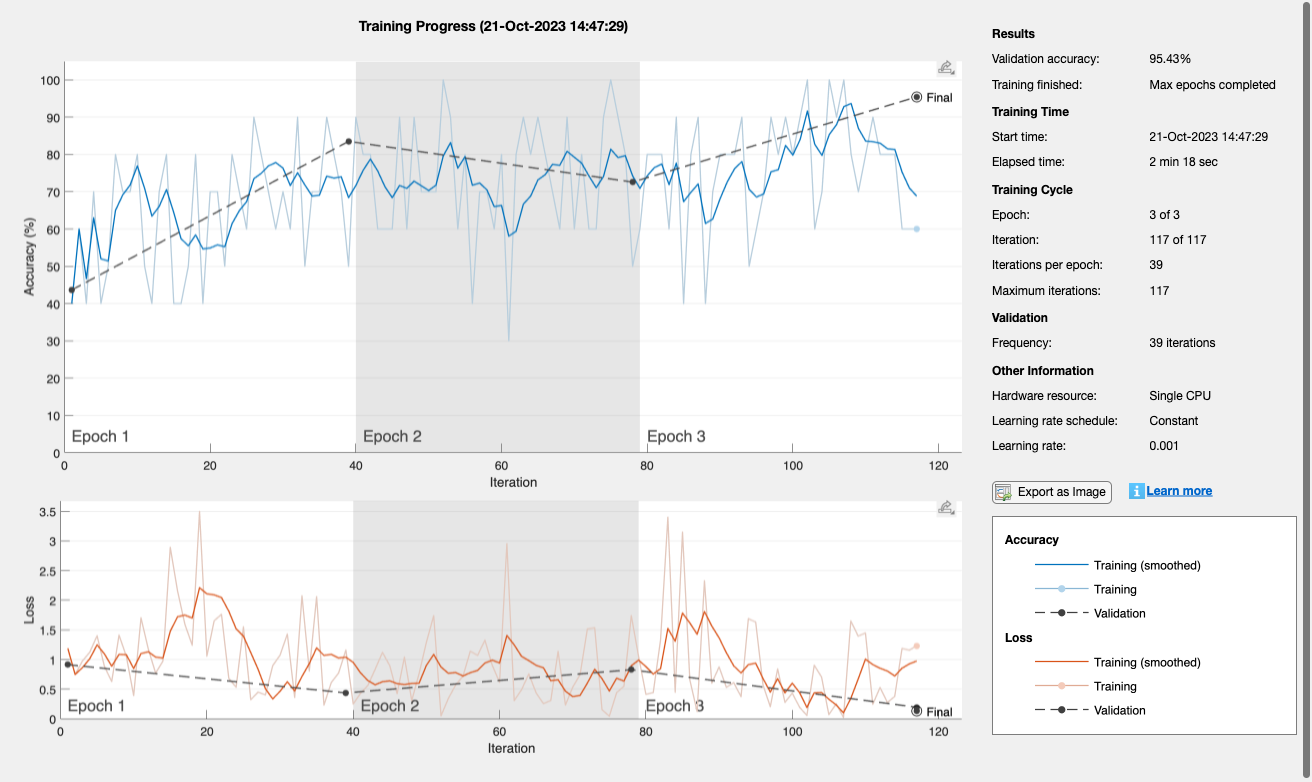

netFreeze = trainNetwork(augimdsTrain,lgraph,options);

Again, this probably could have gone a little bit longer.

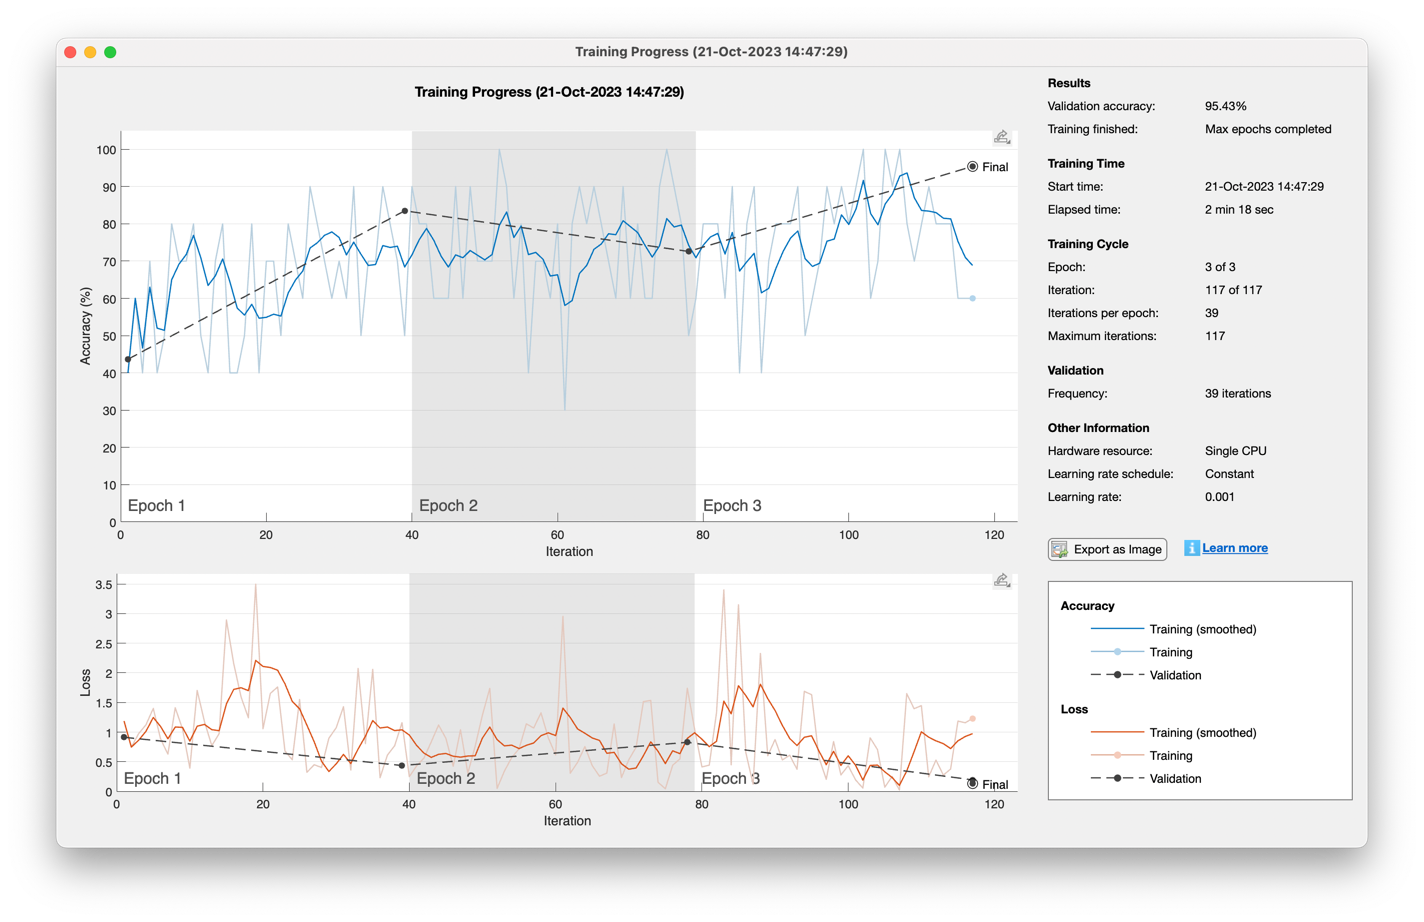

## Classify Validation Images

Classify the validation images using the fine-tuned network, and calculate the classification accuracy.

net = netFreeze;
[YPred,probs] = classify(net, augimdsValidation);
accuracy = mean(YPred == imdsValidate.Labels)

Display four sample validation images with predicted labels and the predicted probabilities of the images having those labels.

idx = [datasample(find(imdsValidate.Labels == "Yes"), 2), ...
    datasample(find(imdsValidate.Labels == "No"), 2)];

accuracy = 0.9543

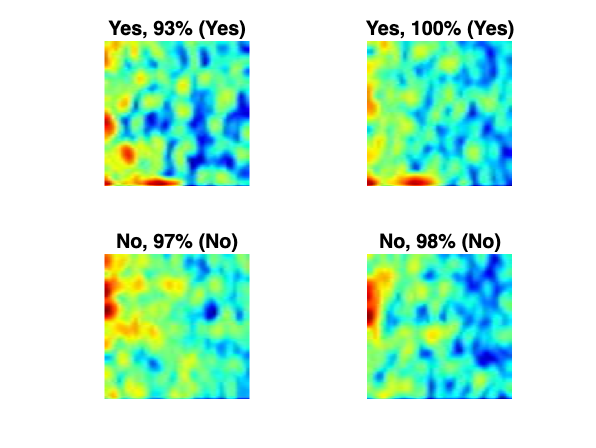

figure
for i = 1:4
    subplot(2,2,i)
    I = imresize(readimage(imdsValidate,idx(i)), inputSize(1:2));
    imshow(I)
    label = YPred(idx(i));
    labelTrue = imdsValidate.Labels(idx(i));
    title(sprintf('%s, %0.0f%% (%s)', label, 100*max(probs(idx(i), :)), labelTrue))
end